# Genetic Algorithm with Matlab Toolbox Examples

#### Prepared by: Yuanfei Wang

#### Date: 05 July 2022

clc
clear
close all

### Model Setup and Initialisation

Initialisation of EPANET Matlab toolkit and loading of .net file.

epanet_path = 'E:\Program Files\MATLAB\R2021b\toolbox\epanet\EPANET-Matlab-Toolkit-master';
net_id = 'example1';
run( [epanet_path,'\start_toolkit'])

EPANET-MATLAB Toolkit Paths Loaded.


net = epanet([net_id,'.inp']);

EPANET version {20200} loaded (EMT version {v2.2.0}).
Loading File "example1.inp"...
Input File "example1.inp" loaded sucessfuly.


### Graph Creation

Use graph theory to plot network connectivity and spatial coordinates.

% Save element count variables
nt = net.getTimeSimulationDuration./3600; % number of time steps in hours
nn = net.NodeJunctionCount;
n0 = net.NodeReservoirCount;
np = net.LinkCount; % count of pipes and valves
D = net.getLinkDiameter';

% Save node index vectors
Reservoir_Idx = net.getNodeReservoirIndex;
Junction_Idx = net.getNodeJunctionIndex;

% Create A12 and A10 incidence matrices
LinkNodesList = net.getLinkNodesIndex;

A = zeros(np,nn+n0);
for k=1:np
    i = LinkNodesList(k,1);
    j = LinkNodesList(k,2);
    A(k,i) = -1;
    A(k,j) = 1;
end

A12 = A(:,Junction_Idx);
A10 = A(:,Reservoir_Idx);
A12 = sparse(A12);
A10 = sparse(A10);

% Obstain node XY and elevation information
XY = zeros(nn+n0,2);
XY(:,1) = net.getNodeCoordinates{1};
XY(:,2) = net.getNodeCoordinates{2};
elev = double(net.getNodeElevations(Junction_Idx))';

% Create adjacency matrix
A = [A12,A10];
AdjA = sparse(size(A,2),size(A,2));

for k = 1:size(A,1)
    node_in = find(A(k,:) == -1);
    node_out = find(A(k,:) == 1);
    AdjA(node_in,node_out) = 1;
    AdjA(node_out,node_in) = 1;
end
gr = graph(AdjA);

hyd_res = net.getComputedHydraulicTimeSeries;
pressure = net.getNodePressure;
demand = net.getNodeActualDemand;
flow = net.getLinkFlows;
head_sim = net.getNodeHydaulicHead;
roughness = net.getLinkRoughnessCoeff;
net.setQualityType('Age');
net.setNodeSourceQuality(1:nn+n0,zeros(nn+n0,1)); % set all node source quality to zero
qua_res = net.getComputedQualityTimeSeries;
LinkIdx = net.getLinkIndex;

%  r = a + (b-a).*rand(N,1) produce random numbers range from [a,b] 
mse_fun = @(sim, obs) (1/size(obs,1)/size(obs,2))*sum(sum((sim - obs).^2));
rand_head = 1 + (1.05-0.95).*rand(nn+n0,1); 
head_obs = head_sim+rand_head';
mse_before = mse_fun(head_sim, head_obs);

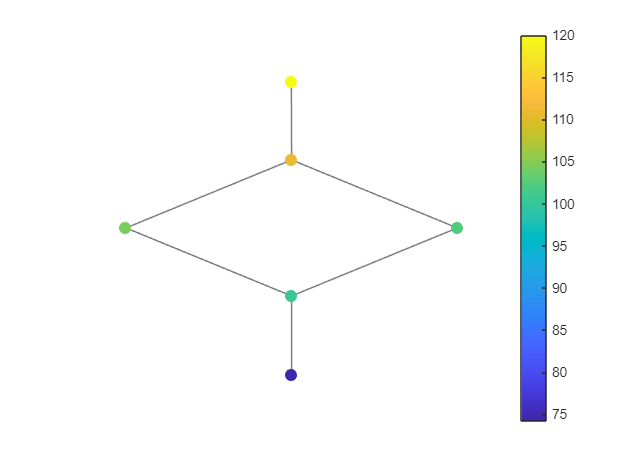

% Plot of network with zero demand junctions for visualisation
figure
p1 = plot(gr);
p1.XData = XY(:,1);
p1.YData = XY(:,2);
p1.LineWidth = 1;
p1.EdgeColor = 'k';
p1.MarkerSize = 7;
p1.NodeColor = 'b';
p1.NodeLabel = '';
p1.NodeFontSize = 11;
p1.NodeLabelColor = [0.6350 0.0780 0.1840];
p1.NodeFontWeight = 'bold';
p1.NodeCData = head_sim;
colorbar
axis('off')

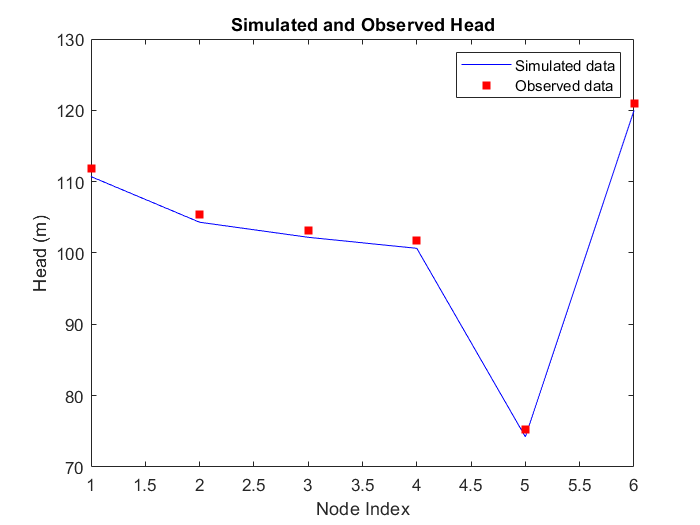

% Plot the calibrated quality-time figure at sensor1
figure,
plot(1:6,head_sim,'-b')
hold on
scatter(1:6,head_obs,'red','filled','square')
legend({'Simulated data','Observed data'})
xlabel('Node Index')
ylabel('Head (m)')
title('Simulated and Observed Head')

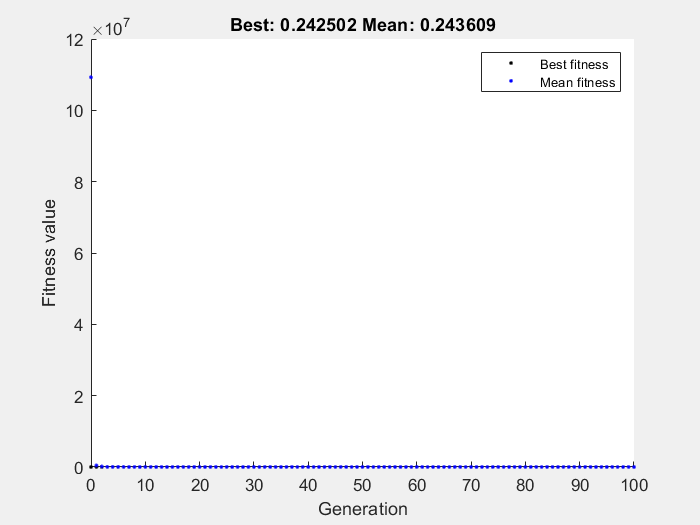


% % Optimize
% options = optimoptions('ga','PopulationType','DoubleVector','PopulationSize',6,'InitialPopulation', ...
%     [50,60,70,80,90,100],'Generations',50,"ConstraintTolerance",1e-3,"PlotFcn","gaplotbestf");

% rng default
options = optimoptions('ga','Display','none','PopulationType','DoubleVector','PopulationSize',6,'InitialPopulation', ...
    [50,60,70,80,90,100],'Generations',100,"ConstraintTolerance",1e-3,"PlotFcn","gaplotbestf");
% options = optimoptions('ga','PopulationType','doubleVector','PopulationSize',4,'')
Mse_function = @(x) Mse(x,head_obs);



[x, fval] = ga(Mse_function,6,[],[],[],[],[],[],[],options);

% Plot the calibrated quality-time figure at sensor1
epanet_path = 'E:\Program Files\MATLAB\R2021b\toolbox\epanet\EPANET-Matlab-Toolkit-master';
net_id = 'example1';
run( [epanet_path,'\start_toolkit'])

EPANET-MATLAB Toolkit Paths Loaded.


net = epanet([net_id,'.inp']);

EPANET version {20200} loaded (EMT version {v2.2.0}).
Loading File "example1.inp"...
Input File "example1.inp" loaded sucessfuly.


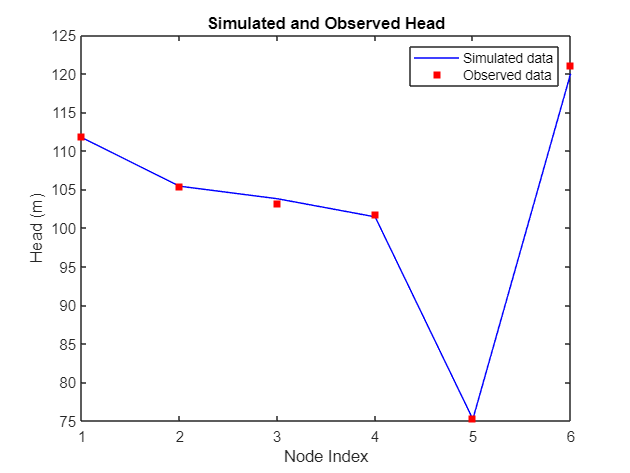

for i = 1:6
    net.setLinkRoughnessCoeff(LinkIdx(i),x(i));
end
net.getLinkRoughnessCoeff;
hyd_ga = net.getComputedHydraulicTimeSeries;
head_ga = net.getNodeHydaulicHead;

figure,
plot(1:6,head_ga,'-b')
hold on
scatter(1:6,head_obs,'red','filled','square')
legend({'Simulated data','Observed data'})
xlabel('Node Index')
ylabel('Head (m)')
title('Simulated and Observed Head')

% Result
fprintf('The mse before ga is %.4f, and the mse after ga is %.4f', mse_before, fval);

The mse before ga is 1.1209, and the mse after ga is 0.2425